# V768 - Measuring Vision with Psychophysics

## Lab 7 - Discrimination vs. Estimation Part II: Motion Direction

This is the second lab in our two-part series on ***discrimination*** and ***estimation*** tasks. In the previous lab, we measured **speed** perception using random dot kinematograms. In this lab, we will measure perception of **motion direction**.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Design a discrimination experiment.

- Design an estimation experiment.

- Compare discrimination and estimation experiments, identifying strengths and weaknesses of each.

### Questions

- Include and write a caption for the LAST figure in Part A, Step 3 (Analyze the data).

- Include and write a caption for the LAST figure in Part B, Step 3 (Analyze the data).

- Reflect on your experiences in the direction discrimination and direction estimation experiments in this lab. Do you think that these experiments measure the same thing? Which of these experiments was easier for you as a subject? Why? Which of these experiments is easier to interpret as an experimenter? Why?

- The previous lab focused on speed perception and this lab focused on direction perception.  Both of these features are components of motion perception.  Reflect on your experiences in both of these labs.  Do you think that the estimation approach was more effective for measuring speed perception or direction perception?  Why?

## Part A. Direction Discrimination Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "2d-motion-direction-discrimination", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 188 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("2d-motion-direction-discrimination", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
discrim_file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
discrim_file_info = struct2table(discrim_file_info);
discrim_file_info.name = string(discrim_file_info.name);
discrim_file_info.folder = string(discrim_file_info.folder);

% find files for given participant
file_mask = startsWith(discrim_file_info.name, participant_id);
discrim_file_info = discrim_file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(discrim_file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(discrim_file_info.name)
end

data files found:
demo_2d-motion-direction-discrimination_2025-02-28_07h12.54.786.csv


**Confirm that all of your data files are listed above.** There should be one file.

#### Load and merge data tables

% build full paths
discrim_file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    discrim_file_info.folder, discrim_file_info.name);

% load data and stack it into one table
warning off;
discrim_data = table;
for ff = 1:n_files
    this_data = readtable(discrim_file_info.path(ff));
    if ismember('thisN', this_data.Properties.VariableNames)
        to_remove = isnan(this_data.thisN);
    elseif ismember('trials_thisN', this_data.Properties.VariableNames)
        to_remove = isnan(this_data.trials_thisN);
    else
        to_remove = 1;
    end
    this_data(to_remove,:) = [];  % remove row on expt instructions
    discrim_data = [discrim_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
to_remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
discrim_data(:,to_remove) = [];

% display data table size
n_trials = size(discrim_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 188


### Step 3. Analyze the data

For this experiment, the stimulus was a random dot kinematogram. You performed a **2IFC** direction discrimination task using staircase methods. In the first interval of each trial, you saw the **reference** stimulus, and in the second interval, you saw the **test** stimulus. You indicated whether the motion you saw in the second interval was ***clockwise*** or ***counterclockwise*** relative to the first interval. There were two reference directions, at 45 degrees and 135 degrees, while the test direction varied around the reference directions.

For each trial, PsychoPy saved the `staircase_intensity`, which contains the offset from the reference direction. The responses were stored in `response` as 'cw' (clockwise) or 'ccw' (counter-clockwise).

% stash the stimulus direction
stim_direction1 = discrim_data.staircase_base_direction;
stim_direction2 = discrim_data.staircase_base_direction+discrim_data.staircase_intensity;

staircases = unique(discrim_data.staircase_label);

% convert the response key to 0 for clockwise and 1 for counterclockwise
response = strcmp(discrim_data.response,'ccw');

#### Visualize the response per trial for each staircase

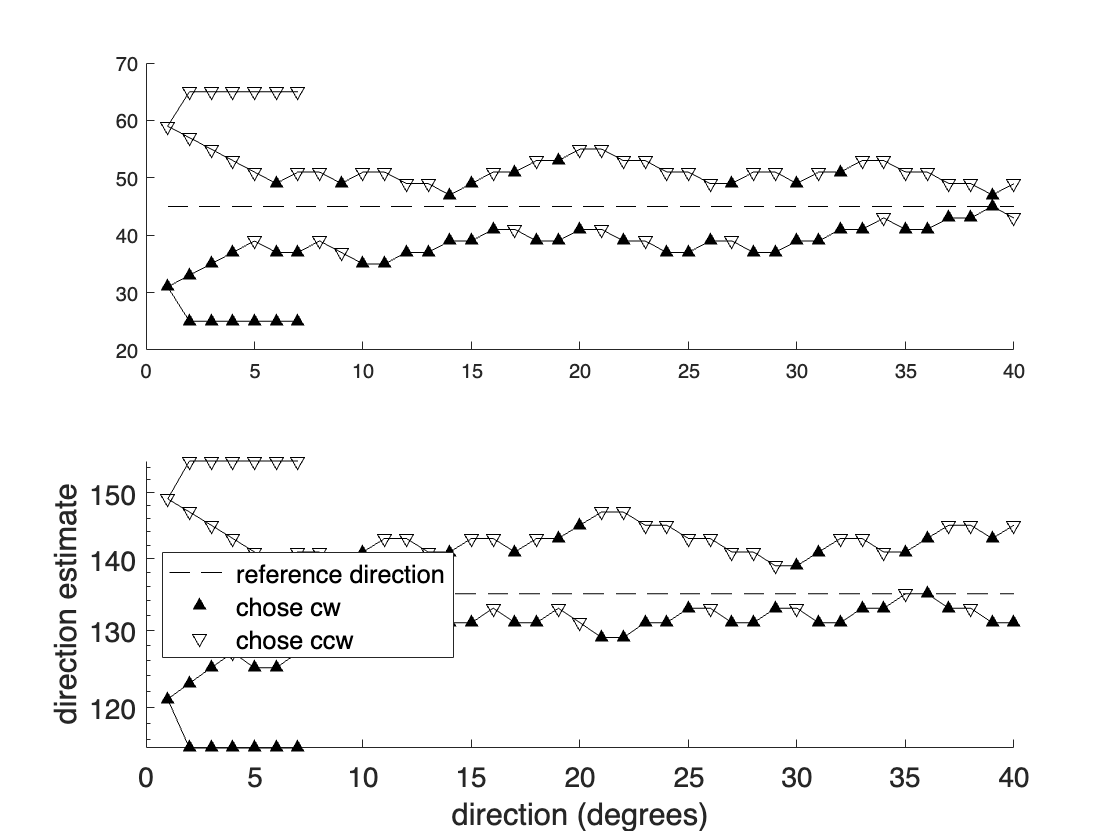

figure; 
ref = unique(discrim_data.staircase_base_direction);

for rr=1:length(ref)
    subplot(2,1,rr); hold on;
    for ii= 1:length(staircases)
        stair_idx = (stim_direction1==ref(rr)) & strcmp(discrim_data.staircase_label,staircases{ii});
        trials = 1:sum(stair_idx);
        leg(1)=plot(trials,stim_direction1(stair_idx),'k--');
        plot(trials,stim_direction2(stair_idx),'k')
        leg(2)=scatter(trials(response(stair_idx)==0),stim_direction2((response==0) & stair_idx),'k^','filled');
        leg(3)=scatter(trials(response(stair_idx)==1),stim_direction2(response==1 &stair_idx),'kv');
    end
end
set(gca,'FontSize',14,'YScale','log')
xlabel('direction (degrees)'); ylabel('direction estimate')
legend(leg,{'reference direction','chose cw','chose ccw'},'Location','West');

drawnow

#### Determine probability of reporting positive (counter-clockwise) difference per condition

Compute performance for each test direction (each comparison level) by calculating the probabaility of reporting that the test direction was counter-clockwise relative to the reference.

discrim_results = array2table([stim_direction1, stim_direction2, response],...
    "VariableNames",["reference_direction","test_direction", "response"]);
discrim_results = grpstats(discrim_results, {'reference_direction', 'test_direction'}, "mean");
discrim_results = renamevars(discrim_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "mean_response"]);
discrim_results.Properties.RowNames = {};
disp(discrim_results)

    reference_direction    test_direction    n_trials    mean_response
    ___________________    ______________    ________    _____________

             45                  25              6                0   
             45                  31              2                0   
             45                  33              1                0   
             45                  35              3                0   
             45                  37             10              0.1   
             45                  39             12          0.33333   
             45                  41              8             0.25   
             45                  43              4              0.5   
             45                  45              1                0   
             45                  47              2                0   
           

#### Fit psychometric curves to the data


for rr=1:length(ref)
    % choose initial parameter values
    init_params = [ref(rr), 5, .1, .1];
    idx = discrim_results.reference_direction==ref(rr);
    % fit psychometric curve to data
    [discrim_params(rr,:), neg_log_likelihood] = fmincon(@(params) ...
        negLogLikelihood(params,...
        (discrim_results.test_direction(idx)),...
        discrim_results.mean_response(idx).*discrim_results.n_trials(idx),...
        discrim_results.n_trials(idx)), init_params,...
        [],[],[],[],[0,0,0,0],[180,100,.5,.5]);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

discrim_param_table = array2table(discrim_params.', ...
    'RowNames',["mu","sigma","gamma","lambda"], 'VariableNames',["fit_45","fit_135"]);
disp(discrim_param_table)

                fit_45       fit_135  
              __________    __________

    mu            45.334        137.48
    sigma         7.1616        7.8176
    gamma     2.7896e-07     6.274e-08
    lambda    1.9299e-07    4.9108e-08



#### Plot the data and the psychometric curves

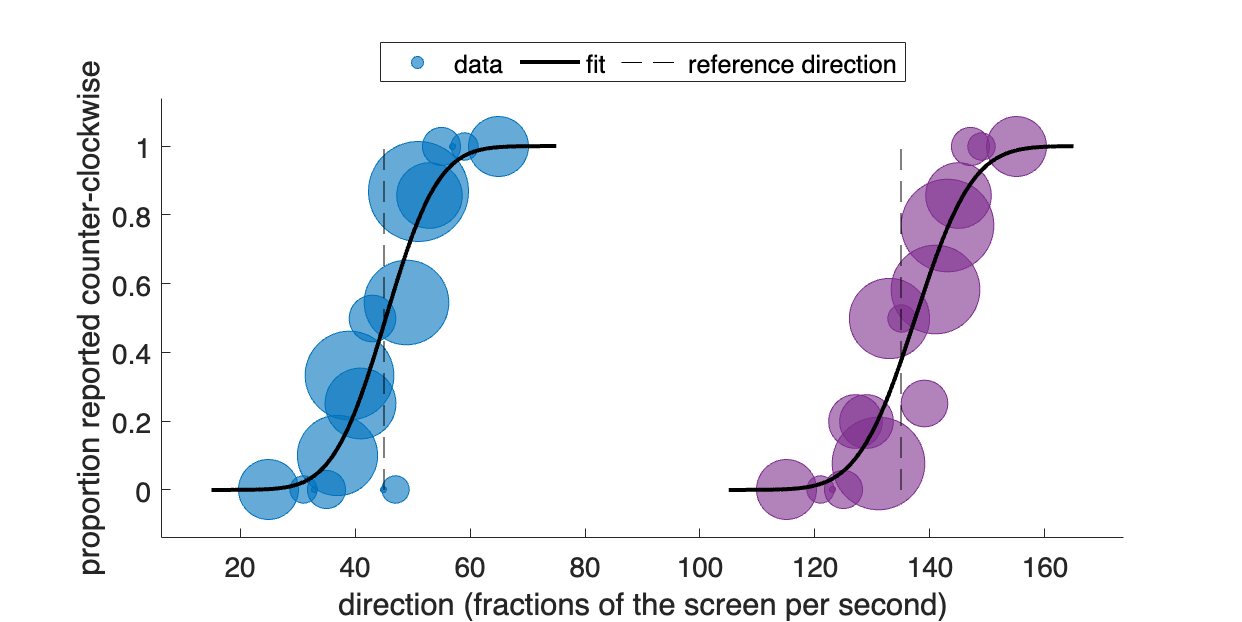

figure(); hold on;

for rr=1:length(ref)
    % calculate curves from fits
    xx= ref(rr) + (-30:30);
    yy = psyfxn(discrim_params(rr,:),xx);
    % plot the data and the fits
    idx = discrim_results.reference_direction==ref(rr);
    bubblechart(discrim_results.test_direction(idx),discrim_results.mean_response(idx), ...
        (discrim_results.n_trials(idx)))
    plot((xx),yy,'k-','LineWidth',2)
    plot(ref(rr)*[1,1],[0,1],'k--')
end
set(gca,'FontSize',14);
set(gcf,'Position',[0,0,900,450])
xlabel('direction (fractions of the screen per second)'); ylabel('proportion reported counter-clockwise')
legend({'data','fit','reference direction'},'Location','northoutside','NumColumns',3)

drawnow

#### Compute and plot the PSEs and JNDs

In Lab 5 and 6, you calculated two metrics from the psychometric curve that you fit to your data. One was the **point of subjective equality (PSE)**, which tells us about the level of bias in your response, and the other was the **just noticeable difference (JND)**, which tells us something about how precisely you can distinguish between different stimulus levels.

Let's calculate those values for this experiment, and then let's visualize them.

% calculate PSE
for rr=1:length(ref)
    pse(rr) = (ipsyfxn(discrim_params(rr,:),.5));
end
discrim_param_table = array2table([pse',ref], ...
     'VariableNames',["PSE","true reference direction"]);
disp(discrim_param_table)

     PSE      true reference direction
    ______    ________________________

    45.334               45           
    137.48              135           



% calculate JND
jnd = discrim_params(:,2)/sqrt(2) % this is in log direction units

jnd =     5.0640
    5.5279


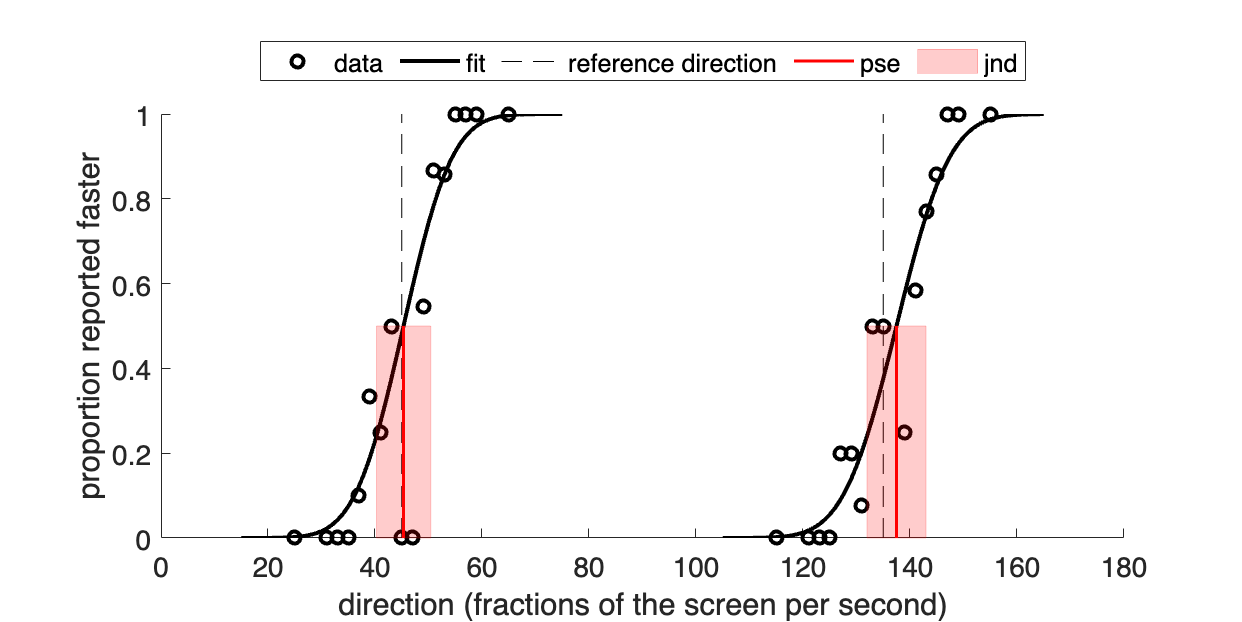

% plot the PSE +/- JND along with the data and fitted curve
figure(); hold on;
for rr=1:length(ref)   
    idx = discrim_results.reference_direction==ref(rr);
    scatter(discrim_results.test_direction(idx),discrim_results.mean_response(idx),'k','LineWidth',2)
    xx= ref(rr) + (-30:30);
    yy = psyfxn(discrim_params(rr,:),xx);
    plot((xx),yy,'k-','LineWidth',2)
    plot(ref(rr)*[1,1],[0,1],'k--')

    plot(pse(rr)*[1,1],[0,.5],'r-','LineWidth',1.5)
    jnd_x = [pse(rr)-jnd(rr),pse(rr)+jnd(rr),pse(rr)+jnd(rr),pse(rr)-jnd(rr),pse(rr)-jnd(rr)];
    jnd_y = [0,0,.5,.5,0];
    patch(jnd_x,jnd_y,'r','FaceAlpha',.2,'EdgeColor','r','EdgeAlpha',.2);
end
set(gca,'FontSize',14);
set(gcf,'Position',[0,0,900,450])
xlabel('direction (fractions of the screen per second)'); ylabel('proportion reported faster')
legend(["data", "fit", "reference direction", "pse", "jnd"],'Location','northoutside','NumColumns',5)

drawnow

**What do you notice?** What do you think about your results?

## Part B.  Direction Estimation Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "2d-motion-direction-estimation", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 112 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("2d-motion-direction-estimation", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
estim_file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
estim_file_info = struct2table(estim_file_info);
estim_file_info.name = string(estim_file_info.name);
estim_file_info.folder = string(estim_file_info.folder);

% find files for given participant
file_mask = startsWith(estim_file_info.name, participant_id);
estim_file_info = estim_file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(estim_file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(estim_file_info.name)
end

data files found:
demo_2d-motion-direction-estimation_2025-02-26_22h06.12.747.csv


**Confirm that all of your data files are listed above.** There should be one file.

#### Load and merge data tables

% build full paths
estim_file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    estim_file_info.folder, estim_file_info.name);

% load data and stack it into one table
warning off;
estim_data = table;
for ff = 1:n_files
    this_data = readtable(estim_file_info.path(ff));
    to_remove = 1;
    this_data(to_remove,:) = [];  % remove row on expt instructions
    estim_data = [estim_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
to_remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
estim_data(:,to_remove) = [];

% display data table size
n_trials = size(estim_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 112


### Step 3. Analyze your data

For this experiment, the stimulus was a random dot kinematogram. The direction of the stimulus varied, and you were asked to report your estimate of the stimulus's direction using a pointer.

For each trial, PsychoPy saved the stimulus direction and your response.

% stash the stimulus direction and estimation data
stim_direction = estim_data.orientation;
estimated_direction = 360-estim_data.pointer_orientation;

#### Visualize the response per trial

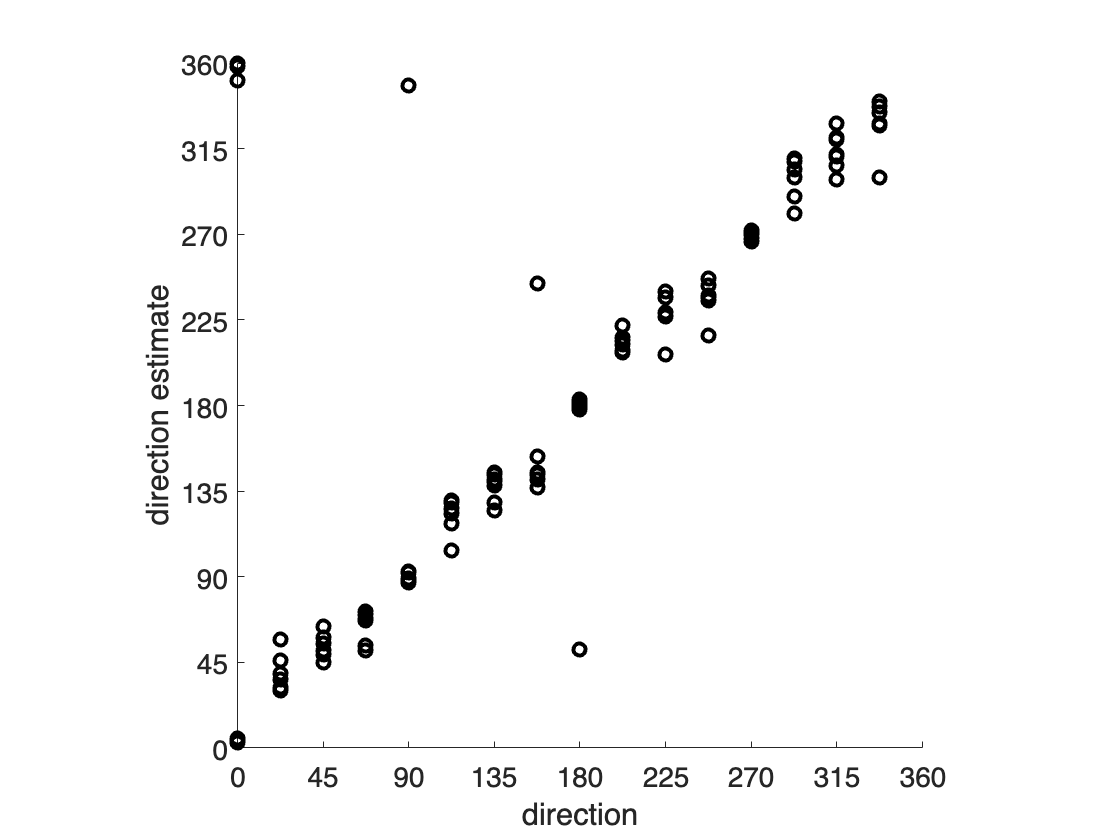

figure; clf;
scatter(stim_direction,estimated_direction,'k','LineWidth',2)
xlabel('direction (fractions of the screen per second)'); ylabel('direction estimate')
xlabel('direction'); ylabel('direction estimate')
set(gca,'FontSize',14,'XTick',0:45:360,'YTick',0:45:360,'XLim',[0,360],'YLim',[0,360])
axis square;

drawnow

#### Determine average rating per test direction

estim_results = array2table([stim_direction, estimated_direction],...
    "VariableNames",["direction", "estimate"]);
estim_results = grpstats(estim_results, "direction", ["circularMean"]);
estim_results = renamevars(estim_results, ...
    ["GroupCount", "circularMean_estimate"], ["n_trials", "circularMean_estimate"]);
estim_results.Properties.RowNames = {};
disp(estim_results)

    direction    n_trials    circularMean_estimate
    _________    ________    _____________________

          0         7               0.14706       
       22.5         7                38.677       
         45         7                54.285       
       67.5         7                64.305       
         90         7                80.575       
      112.5         7                121.89       
        135         7                137.44       
      157.5         7                153.63       
        180         7                172.22       
      202.5         7                213.57       
        225         7                227.76       
      247.5         7                236.47       
        270         7                269.86       
      292.5         7                299.03       
        315         7                313.86       
      337.5         7         

#### Plot average rating as a function of test direction

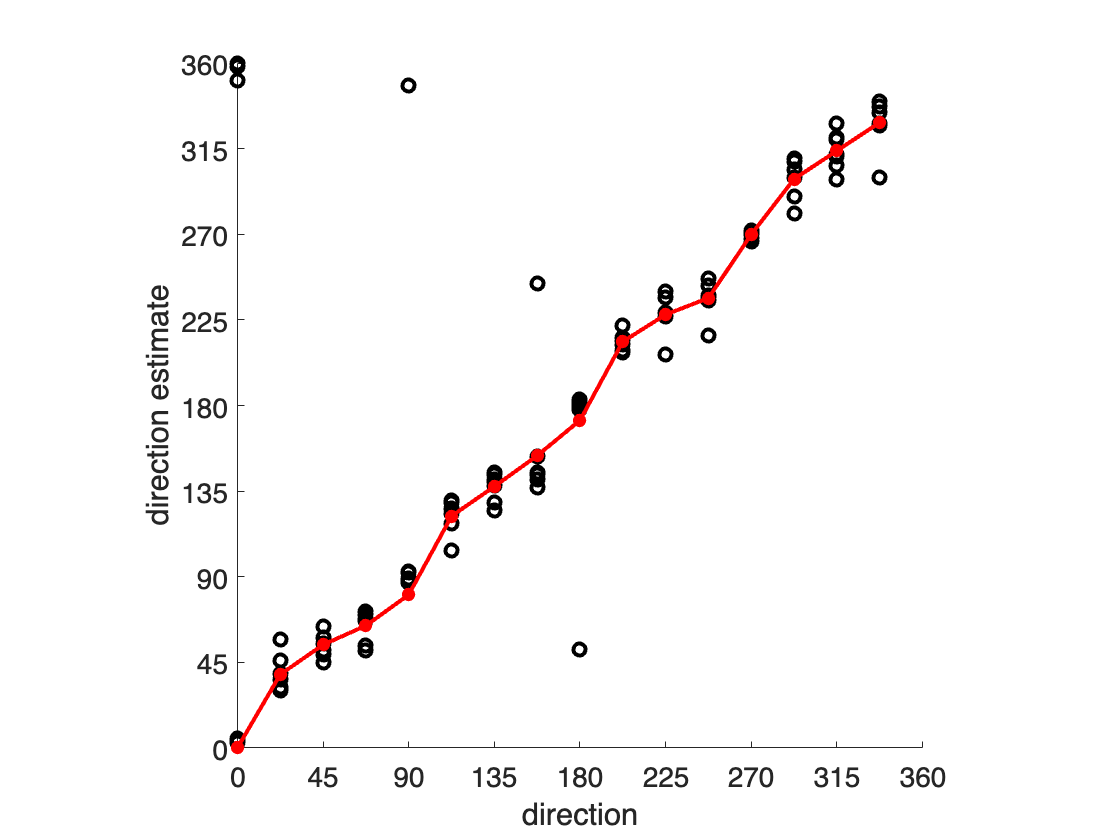

figure; hold on;
scatter(stim_direction,estimated_direction,'k','LineWidth',2)
plot(estim_results.direction,estim_results.circularMean_estimate,'r.-','MarkerSize',20,'LineWidth',2)
xlabel('direction'); ylabel('direction estimate')
set(gca,'FontSize',14,'XTick',0:45:360,'YTick',0:45:360,'XLim',[0,360],'YLim',[0,360])
axis square;

drawnow

**What do you notice?** What do you think about your results?